# Death Seasonality in Germany

## Import data from spreadsheet

opts = spreadsheetImportOptions("NumVariables", 48);

% Specify sheet and range
opts.Sheet = "Germany";
opts.DataRange = "P2:BK62";

% Specify column names and types
opts.VariableNames = ["January1", "January2", "January3", "January4", "February1", "February2", "February3", "February4", "March1", "March2", "March3", "March4", "April1", "April2", "April3", "April4", "May1", "May2", "May3", "May4", "June1", "June2", "June3", "June4", "July1", "July2", "July3", "July4", "August1", "August2", "August3", "August4", "September1", "September2", "September3", "September4", "October1", "October2", "October3", "October4", "November1", "November2", "November3", "November4", "December1", "December2", "December3", "December4"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
myDeath = readtable("Deaths_in_Germany.xlsx", opts, "UseExcel", false)

myDeath = 61×48 table
    January1    January2    January3    January4    February1    February2    February3    February4    March1    March2    March3    March4    April1    April2    April3    April4    May1     May2     May3     May4     June1    June2    June3    June4    July1    July2    July3    July4    August1    August2    August3    August4    September1    September2    September3    


% Clear temporary variables
clear opts

## Plot death seasonality

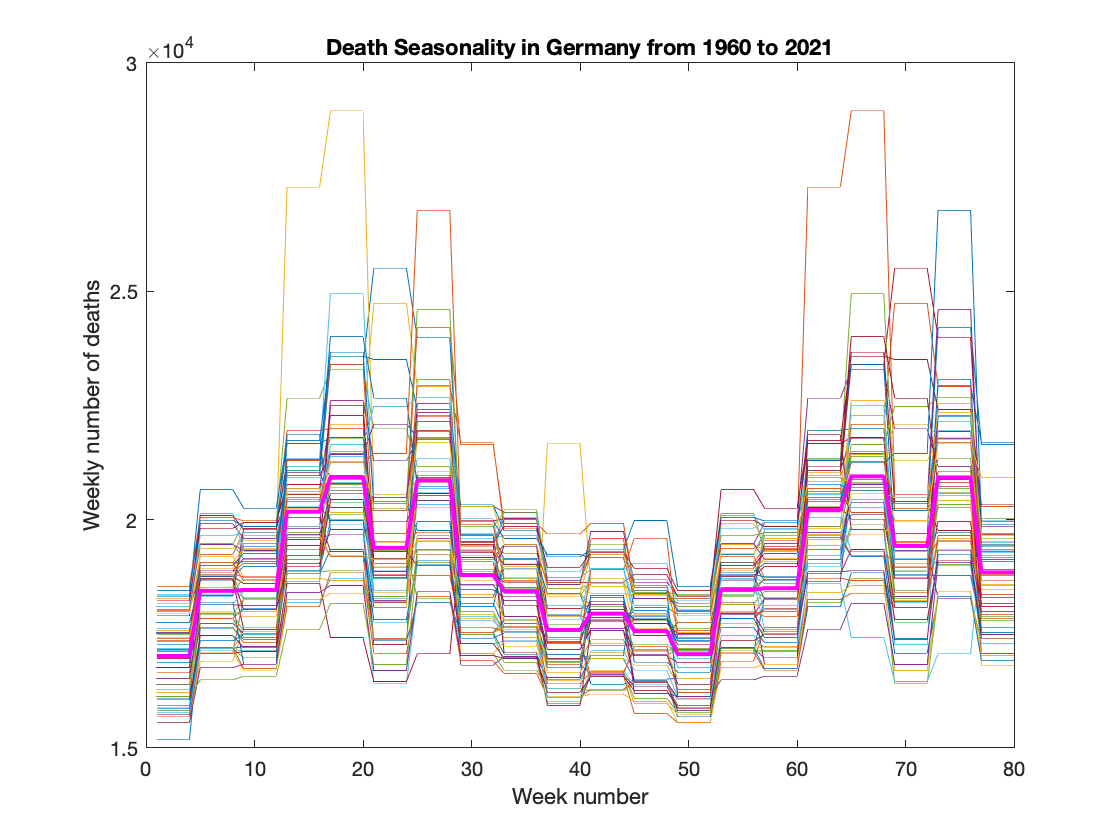

myDeath = table2array(myDeath);

merged_year = zeros(59, 80);

for year = 2:60
    
    last_year = myDeath(year - 1, :);
    current_year = myDeath(year, :);
    next_year = myDeath(year + 1, :);

    merged_year(year - 1, :) = [last_year(end-15:end), current_year, next_year(1:16)];

    plot(1:80, merged_year(year - 1, :))
    hold on

end

plot(1:80, mean(merged_year), 'Color', "m", 'LineWidth', 2, 'LineStyle', "-")

title('Death Seasonality in Germany from 1960 to 2021')

xlabel('Week number')
ylabel('Weekly number of deaths')

hold off

## Determine descriptive statistics

total_deaths = sum(merged_year, 2)

total_deaths =      1455991
     1515487
     1481534
     1470809
     1517650
     1529309
     1586509
     1628962
     1660490
     1649122



max_deaths = max(total_deaths)

max_deaths = 1660490

worst_year = 1960 + find(total_deaths == max_deaths)

worst_year = 1969


min_deaths = min(total_deaths)

min_deaths = 1378029

best_year = 1960 + find(total_deaths == min_deaths)

best_year = 2006


mean_deaths = mean(total_deaths)

mean_deaths = 1.5198e+06

sd_deaths = std(total_deaths)

sd_deaths = 7.8962e+04